clear
clc

Import

addpath("srcs\all_func\");
aneu_imgs = imageDatastore("srcs\imgs\Aneurysm\");
nor_imgs = imageDatastore("srcs\imgs\Normal\");
numfiles1 = numel(aneu_imgs.Files);
numfiles2 = numel(nor_imgs.Files);

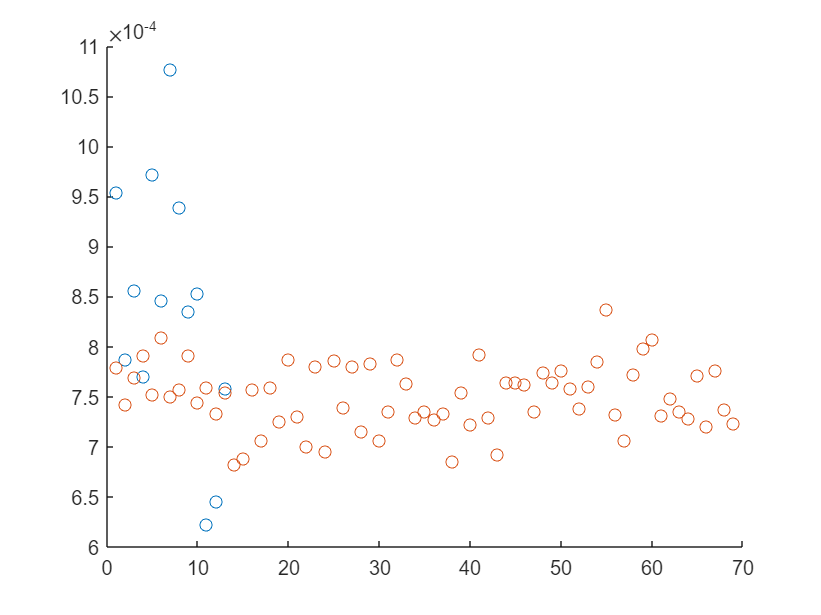


bwratio1 = zeros(1, numfiles1);
bwratio2 = zeros(1, numfiles2);
for i = 1 : numfiles1
    bwratio1(i) = cal_bwratio(readimage(aneu_imgs, i));
end

for i = 1 : numfiles2
    bwratio2(i) = cal_bwratio_crop(readimage(nor_imgs, i));
end

scatter([1 : numfiles1], bwratio1);
hold on;
scatter([1 : numfiles2], bwratio2);

Test 

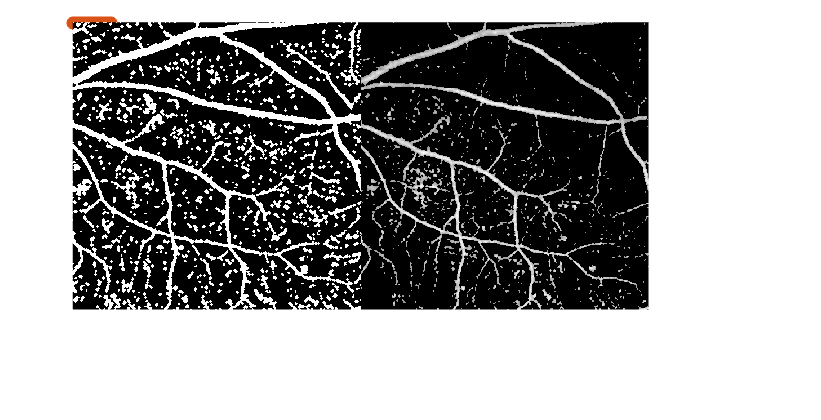

test_img = readimage(aneu_imgs, 1);
test_img = AllFilters.imagePrepare(test_img);
org = test_img;
test_nor = readimage(nor_imgs, 1);
test_nor = imcrop(test_nor, [0, 0, 1024, 965]);
test_nor = AllFilters.wienerFilter(test_nor, [4 4]);
fil_img = AllFilters.wienerFilter(test_img, [4 4]);
fil_img = AllFilters.imClose(fil_img, 2);
% test_img = AllFilters.imagePrepare(test_img);
% test_img = imbinarize(test_img, 'adaptive');
% res = test_img - fil_img;

% imshowpair(test_img, fil_img, 'montage');
% imshow(res);
res1 = test_kmean(test_img);
res2 = test_kmean(test_nor);

imshowpair(fil_img, res1, 'montage');

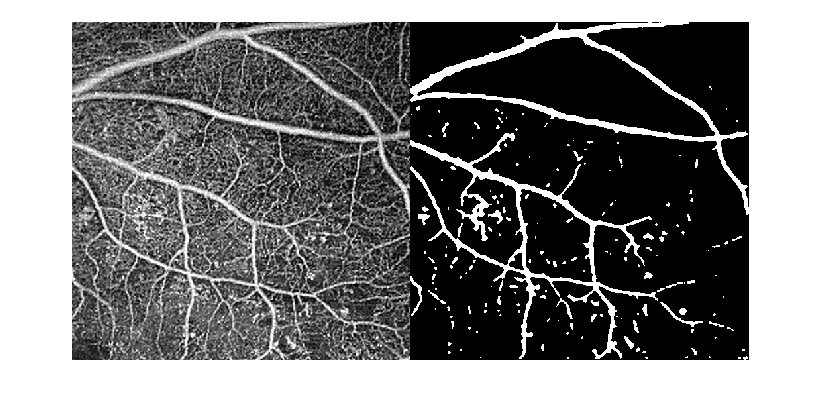

res1 = AllFilters.medFilter(res1, [6 6]);
imshowpair(org, imbinarize(res1, 'adaptive'), 'montage');

Local Functions

function res = cal_bwratio(img)
%img = imcrop(img, [0, 0, 1024, 965]);
img = AllFilters.wienerFilter(img, [4 4]);
img = AllFilters.imClose(img, 2);
sum_pixel = sum(sum(img));
sum_pixel = sum_pixel/255;
[m, n] = size(img);
res = sum_pixel / (m * n);
end

function res = cal_bwratio_crop(img)
img = imcrop(img, [0, 0, 1024, 965]);
img = AllFilters.wienerFilter(img, [4 4]);
img = AllFilters.imClose(img, 2);
sum_pixel = sum(sum(img));
sum_pixel = sum_pixel/255;
[m, n] = size(img);
res = sum_pixel / (m * n);
end

function res = test_kmean(img)
img = AllFilters.wienerFilter(img, [5 5]);
morph_img = AllFilters.imClose(img, 3);
L = imsegkmeans(img, 3, NumAttempts=10);

cluster_img = get_cluster(img, L, 1);
min_diff = img_diffsq(cluster_img, morph_img);
min_cluster = cluster_img;
for i = 2 : 3
    cluster_img = get_cluster(img, L, i);
    dif = img_diffsq(cluster_img, morph_img);
    if dif < min_diff
        min_diff = dif;
        min_cluster = cluster_img;
    end
end
res = min_cluster;
end

function res = get_cluster(img, L, i)
mask1 = L == i;
res = img.*uint8(mask1);
end

function diff = img_diffsq(a, b)
a = AllFilters.imagePrepare(a);
b = AllFilters.imagePrepare(b);
a = imbinarize(a, 'adaptive');
b = imbinarize(b, 'adaptive');
[m, n] = size(a);
diff = 0;
for i = 1 : m
    for j = 1 : n
        diff = diff + (a(i, j) - b(i,j))^2;
    end
end
end